# Informe Laboratorio: Análisis Numérico

# Práctica No. 3

**Juan Pablo Jiménez Gómez **

**Código: 2173051**

**Grupo: B2**

*Escuela de ingeniería de sistemas e informática*

*Universidad Industrial de Santander*

26 de Noviembre de 2020

## **Introducción**

The Newthon-Rhapson method is an algorithm that is used to determine different types of approximations for the roots of a real function, or to determine the maximum or minimum of a function of a function. A required condition for this process is that the functions be differentiable from the initial value for the root xi taken as any value, in such a way that the method converges to the nearest root.

In the following laboratory, this method is evaluated using the MATLAB platform in order to study the iterative behavior of a proposed function, the derivative of this function, its respective error, roots and visual form through different exercises that they put into practice our knowledge.

## **3 Implementing**

- 2.0 points) Create a Matlab function called my newton function name lastname() to find the root of a function using the Newton-Raphson method. The arguments of the function must be: the function to be evaluated f(x) (as an inline function), the initial point [p0], the derivate of the function f´(x) (as an inline function), and the stopping criteria (the number of iterationsor the error). Make a script called run 2a name lastname:m in which you use the createdfunction to find the three roots of the function f(x) = x^3 -13x^2 - 297.5x + 0.00000375e^x. You have to choose a proper initial point for each root. For instance,

fun = @ XXXXXX;

der = @ XXXXXX;

p0 = XX;

Iter=X;

root=my newton function name lastname(fun,p0,der,Iter);

Myfun = @(x) x^3+13.*(x^2)-297.5.*x+0.00000375*exp(x);
der = @(x) 3.*(x^2)-26.*x-297.5+0.00000375*exp(x);
p0= 1;
iter=5;
root = my_newton_function_Juan_Pablo_Jimenez_Gomez(Myfun,der,p0,iter);

La ra�z encontrada es:
   1.2605e-08



**Analysis:**

For the first exercise we are asked to program a function in order to find the root of a given function using the Newton-Raphson method. The first thing that was done was to define variables, the main thing has been the function that they give us x^3+13.*(x^2)-297.5.*x+0.00000375*exp(x) And after that define its respective derivative 3.*(x^2)-26.*x-297.5+0.00000375*exp(x), In addition to that we define the initial point that we are going to take and the number of iterations that we are going to do to carry out the process. In the continuation of the code found in the part of the annexes we define our pk as the variable that will take the value to 0zero, we will equal k to zero because it is our respective counter for the iterations, and we will create a for loop to evaluate the function in such a way that This continues running until the number of iterations that was set, this process is done so that when the function is being worked, the value of pk is not equal to zero or does not exceed the previously programmed iterations. After this we apply the Newton-Raphson method to the value of pk and we recount the said iteration with the k that we initially define as zero, all this so that in the final result the root that we seek to determine is printed, thus concluding the exercise .

- 1.5 points) Modify the function in the previous item such that it prints the values:

 k : Number of current iteration

 $x_k$ : Value of the root at iteration k

 f($x_k$) : Value of the function evaluated in $x_k$

 f´($x_k$) : Value of the derivative evaluated in $x_k$

 | $x_k$`- `$x_{k-1}$ |: Absolute error

Myfun = @(x) x^3+13.*(x^2)-297.5.*x+0.00000375*exp(x);
der = @(x) 3.*(x^2)-26.*x-297.5+0.00000375*exp(x);
p0 = 1;
iter = 2;
 [ root]= my_newton_function_Juan_Pablo_Jimenez_Gomez_modify(Myfun,der,p0,iter);

   table of required results
     Iter      Raiz      F(x)      dF(x)     Error
    2.0000    0.0017   -0.5116 -297.5447    0.1137



**Analysis:**

 In the following exercise we are asked to modify the function in such a way that the following values are printed: Iter, Root, F (x), dF (x), Error. If we realize there is not much difference with the previous exercise, but in this case we are asked to determine the error which will be something that will make us modify the code proposed in exercise 1. We define the variables that we are going to evaluate, both the function as its respective derivative, the p0 and the number of iterations. When programming the code we define pk as zero and we take our iterative variable k as zero, we implement the for loop to evaluate the function. After that we apply the Newton-Raphson method to the function we have, and this time we calculate the error of the function, where we subtract the value of pk from the function p0, and we propose the new value for the variable k, this with the so that the end of the cycle is determined when the error is equal to zero. Finally we define the table of values and the variables as an output to be calculated to finally print the results.

- (1.5 points) Create a Matlab function called my visual newton function name lastname() to visualize the behaviour of the Newton method. The arguments of the function must be: the function to be evaluated f(x) (as an inline function), the initial point [p0], the derivate of the function, fp(x), and the number of iterations. Make a script called run 2b name lastname.m in which you use the created function to visualize the behavior of the Newton method when solving the exercise in 3 and conclude about the convergence of the method. For instance,

fun = @ XXXXXX;

der = @ XXXXXX;

p0 = XX;

Iter= XX

root=my visual newton function name lastname(fun,p0,der,Iter);

Myfun = @(x) x.^3+13*x.^2-297.5*x+0.00000375*exp(x);
der = @(x) 3.*(x^2)-26.*x-297.5+0.00000375*exp(x);
iter = 2;
p0 = 5;

Visual verification

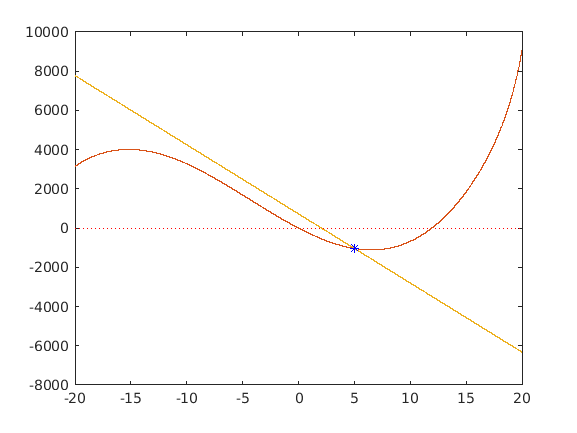

The root is:
    0.0235



my_visual_newton_function_Juan_Pablo_Jimenez_Gomez(Myfun,p0,der,iter);

**Analysis:**

For the third and last point, we are asked to graph the proposed function using the Newton-Raphson method in order to see its convergence, and the iterations according to its initial point p0, in addition to calculating the root of said function. Then the variables are defined as has been done in previous exercises, and the function is programmed in such a way that it shows the graph for each iteration in such a way that said approximation of the root can be shown, we set our pk to zero and our iterative variable k to zero, we define the value that x will take to indicate the interval and the size of the slope with which we are going to work and later to graph, we create the for loop to evaluate the function we have. After this we define the plot functions to be able to make the graph, as well as assign a value to y. Finally we evaluate the function with the well-known Newton-Raphson method and finally we print the value that this root will give us in addition to being able to visualize the graph that works for the respective initial points p0 and iterations that are digitized and showing their respective convergence, thus achieving the goal of this exercise.

## **Anexes: **

**my_newton_function_Juan_Pablo_Jimenez_Gomez**

function pk= my_newton_function_Juan_Pablo_Jimenez_Gomez(Myfun,der,p0,iter);
pk=p0;
k=0;
for i=1:iter
    if der (pk)==0 || k>iter
        disp('You cant do the division by 0');
        break;
    end
    pk = p0 - (Myfun(pk)/der(pk));
    p0 = pk;
    k=k+1;  
end
 disp('The root is:');
 disp(pk); 
end


**my_newton_function_Juan_Pablo_Jimenez_Gomez_modify**

function [pk] = my_newton_function_Juan_Pablo_Jimenez_Gomez_modify(Myfun,der,p0,iter);
pk=0;
k=0;
for i=1:iter
    if der (pk)==0 || k>iter
        disp('You cant do the division by 0');
        break;
    end
    pk= p0 -feval(Myfun,p0)/feval (der,p0);
    err=abs(pk-p0);
    p0 = pk;
    k=k+1;
   Results=[k ,pk ,Myfun(pk) ,der(pk),err];   
end
 disp('   table of required results');
disp('     Iter      Raiz      F(x)      dF(x)     Error');
 disp(Results);
end


**my_visual_newton_function_Juan_Pablo_Jimenez_Gomez**

function[pk] = my_visual_newton_function_Juan_Pablo_Jimenez_Gomez(Myfun, p0,der,iter)
pk = 0;
k=0;
x = -20:0.00001:20;
for i=1:iter
       if der (pk)==0 || k>iter
        disp('You cant do the division by 0');
        break;
    end
   pk = p0 - (Myfun(pk)/der(pk));
   p0=pk;
   k=k+1;
    plot(x, zeros(size(x)), 'r:');
    hold on
    plot(x, Myfun(x));
    hold on
    y = der(pk)*(x - pk) + Myfun(pk);
    plot(x, y);
    hold on
    plot(pk, Myfun(pk), 'b*');
    pause(pk);
    close all
   pk = p0 - (Myfun(pk)/der(pk));
   p0=pk;
   k=k+1;
end
 disp('The root is:');
 disp(pk); 
end

## **References: **

Método de Newton. (2020). Retrieved 26 November 2020, from [https://es.wikipedia.org/wiki/M%C3%A9todo_de_Newton](https://es.wikipedia.org/wiki/M%C3%A9todo_de_Newton)

(2020). Retrieved 26 November 2020, from [http://www.ehu.eus/juancarlos.gorostizaga/mn11b/temas/newton_ecuac.pdf](http://www.ehu.eus/juancarlos.gorostizaga/mn11b/temas/newton_ecuac.pdf)

Métodos Numéricos. (2020). Retrieved 26 November 2020, from [http://test.cua.uam.mx/MN/Methods/Raices/NewtonRaphson/NewtonRaphson.php](http://test.cua.uam.mx/MN/Methods/Raices/NewtonRaphson/NewtonRaphson.php)

하람, 유. (2020). Solutions Manual to accompany Applied Numerical Methods With MATLAB for Engineers and Scientists. Retrieved 26 November 2020, from [https://www.academia.edu/8589710/Solutions_Manual_to_accompany_Applied_Numerical_Methods_With_MATLAB_for_Engineers_and_Scientists](https://www.academia.edu/8589710/Solutions_Manual_to_accompany_Applied_Numerical_Methods_With_MATLAB_for_Engineers_and_Scientists)